# Design of FIR filter using Rectangular Window

## Prepared by Ganesh N. Jadhav, KKWIEER, Nashik

%% Input data
clear all; clc;
% Cut off frequencies 
wc1=0.2*pi   % lower cut-off frequency

wc1 = 0.6283

wc2=0.5*pi   % higher cut-off frequency

wc2 = 1.5708

N=7         % Filter length (order)

N = 7

a=(N-1)/2    % Center point of filter

a = 3

## Design of low pass FIR filter with wc1


$$\begin{array}{l}
\mathrm{Desired}\;\mathrm{Inverse}\;\mathrm{Fourier}\;\mathrm{Transform}\;\mathrm{is}\\
h_d \left(n\right)=\frac{\sin \left(\omega_{\mathrm{c1}} \left(n-a\right)\right)}{\pi \left(n-a\right)}\;\;\;\mathrm{for}\;n\not= 0\\
h_d \left(n\right)=\frac{\omega_{\mathrm{c1}} }{\pi }\;\;\;\;\;\mathrm{for}\;n=0
\end{array}$$


% Desired inverse fourier transform
i=1;
T=1;
Wr=ones(1:N)

Wr = Wr(:,:,1,1,1,1,1) =

     1     1


Wr(:,:,2,1,1,1,1) =

     1     1


Wr(:,:,3,1,1,1,1) =

     1     1


Wr(:,:,1,2,1,1,1) =

     1     1


Wr(:,:,2,2,1,1,1) =

     1     1


Wr(:,:,3,2,1,1,1) =

     1     1


Wr(:,:,1,3,1,1,1) =

     1     1


Wr(:,:,2,3,1,1,1) =

     1     1


Wr(:,:,3,3,1,1,1) =

     1     1


Wr(:,:,1,4,1,1,1) =

     1     1


Wr(:,:,2,4,1,1,1) =

     1     1


Wr(:,:,3,4,1,1,1) =

     1     1


Wr(:,:,1,1,2,1,1) =

     1     1


Wr(:,:,2,1,2,1,1) =

     1     1


Wr(:,:,3,1,2,1,1) =

     1     1


Wr(:,:,1,2,2,1,1) =

     1     1


Wr(:,:,2,2,2,1,1) =

     1     1


Wr(:,:,3,2,2,1,1) =

     1     1


Wr(:,:,1,3,2,1,1) =

     1     1


Wr(:,:,2,3,2,1,1) =

     1     1


Wr(:,:,3,3,2,1,1) =

     1     1


Wr(:,:,1,4,2,1,1) =

     1     1


Wr(:,:,2,4,2,1,1) =

     1     1


Wr(:,:,3,4,2,1,1) =

     1     1


Wr(:,:,1,1,3,1,1) =

     1     1


Wr(:,:,2,1,3,1,1) =

     1     1


Wr(:,:,3,1,3,1,1) =

     1     1


Wr(:,:,1,2,3,1,1) =

  

for n=0:N-1
    if n==a
        hd(i)=(wc1/pi);
        i=i+1;
    else
        hd(i)=(sin(wc1*(n-a))/(pi*(n-a)));
        i=i+1;
    end
end
hd

hd =     0.1009    0.1514    0.1871    0.2000    0.1871    0.1514    0.1009


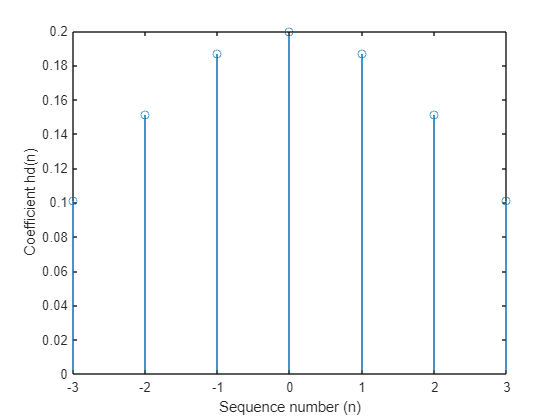

n=-a:a;
figure
stem(n,hd)
xlabel('Sequence number (n)')
ylabel('Coefficient hd(n)')

% Transfer function of IIR filter
numz=hd;
denz=1;
Hz=tf(numz,denz,T)

Hz =
 
  0.1009 z^6 + 0.1514 z^5 + 0.1871 z^4 + 0.2 z^3 + 0.1871 z^2 + 0.1514 z + 0.1009
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


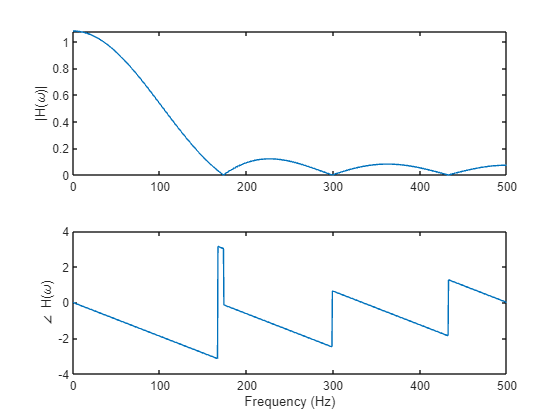

% frequency response of FIR filter
Fs=1000;
[H,f]=freqz(numz,denz,1024,Fs);
H_mag=abs(H);
H_ang=angle(H);
figure
subplot(2,1,1)
plot(f,H_mag)
ylabel('|H(\omega)|')
subplot(2,1,2)
plot(f,H_ang)
ylabel('\angle H(\omega)')
xlabel('Frequency (Hz)')

## Design of high pass FIR filter with wc2


$$\begin{array}{l}
\mathrm{Desired}\;\mathrm{Inverse}\;\mathrm{Fourier}\;\mathrm{Transform}\;\mathrm{is}\\
h_d \left(n\right)=\frac{\sin \left(\pi \left(n-a\right)\right)-\sin \left(\omega_{\mathrm{c2}} \left(n-a\right)\right)}{\pi \left(n-a\right)}\;\;\;\mathrm{for}\;n\not= 0\\
h_d \left(n\right)=1-\frac{\omega_{\mathrm{c2}} }{\pi }\;\;\;\;\;\mathrm{for}\;n=0
\end{array}$$


% Desired inverse fourier transform
i=1;
T=1;
for n=0:N-1
    if n==a
        hd(i)=1-wc2/pi;
        i=i+1;
    else
        hd(i)=(sin(pi*(n-a))-sin(wc2*(n-a)))/(pi*(n-a));
        i=i+1;
    end
end
hd

hd =     0.1061   -0.0000   -0.3183    0.5000   -0.3183   -0.0000    0.1061


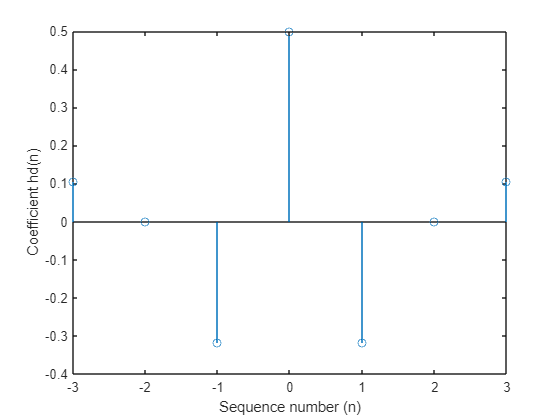

figure
n=-a:a;
stem(n,hd)
xlabel('Sequence number (n)')
ylabel('Coefficient hd(n)')

% Transfer function of IIR filter
numz=hd;
denz=1;
Hz=tf(numz,denz,T)

Hz =
 
  0.1061 z^6 - 5.847e-17 z^5 - 0.3183 z^4 + 0.5 z^3 - 0.3183 z^2 - 5.847e-17 z + 0.1061
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


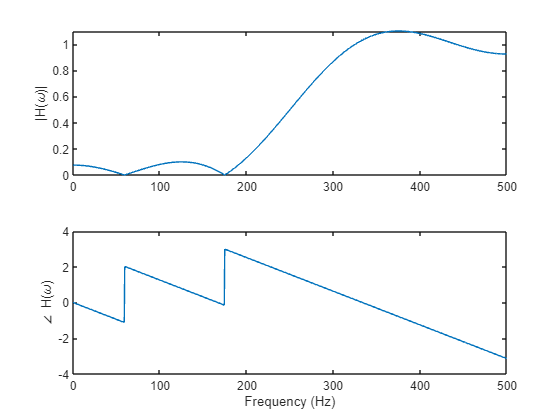

% frequency response of FIR filter
Fs=1000;
[H,f]=freqz(numz,denz,1024,Fs);
H_mag=abs(H);
H_ang=angle(H);
figure
subplot(2,1,1)
plot(f,H_mag)
ylabel('|H(\omega)|')
subplot(2,1,2)
plot(f,H_ang)
ylabel('\angle H(\omega)')
xlabel('Frequency (Hz)')

## Design of band pass FIR filter with wc1 and wc2


$$\begin{array}{l}
\mathrm{Desired}\;\mathrm{Inverse}\;\mathrm{Fourier}\;\mathrm{Transform}\;\mathrm{is}\\
h_d \left(n\right)=\frac{\sin \left(\omega_{\mathrm{c2}} \left(n-a\right)\right)-\sin \left(\omega_{\mathrm{c1}} \left(n-a\right)\right)}{\pi \left(n-a\right)}\;\;\;\mathrm{for}\;n\not= 0\\
h_d \left(n\right)=\frac{\omega_{\mathrm{c2}} -\omega_{\mathrm{c1}} }{\pi }\;\;\;\;\;\mathrm{for}\;n=0
\end{array}$$


% Desired inverse fourier transform
i=1;
T=1;
for n=0:N-1
    if n==a
        hd(i)=(wc2-wc1)/pi;
        i=i+1;
    else
        hd(i)=(sin(wc2*(n-a))-sin(wc1*(n-a)))/(pi*(n-a));
        i=i+1;
    end
end
hd

hd =    -0.2070   -0.1514    0.1312    0.3000    0.1312   -0.1514   -0.2070


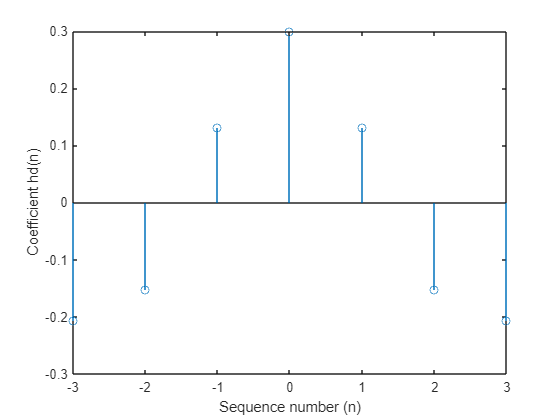

figure
n=-a:a;
stem(n,hd)
xlabel('Sequence number (n)')
ylabel('Coefficient hd(n)')

% Transfer function of IIR filter
numz=hd;
denz=1;
Hz=tf(numz,denz,T)

Hz =
 
  -0.207 z^6 - 0.1514 z^5 + 0.1312 z^4 + 0.3 z^3 + 0.1312 z^2 - 0.1514 z - 0.207
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


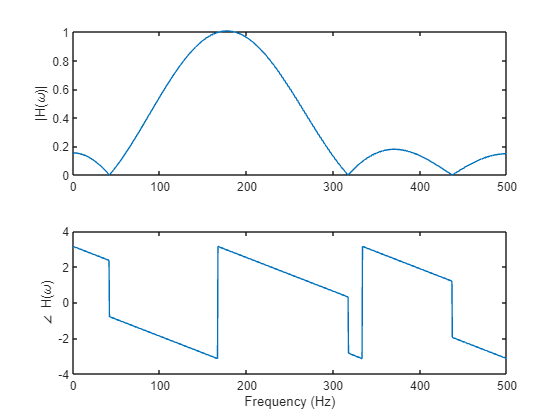

% frequency response of FIR filter
Fs=1000;
[H,f]=freqz(numz,denz,1024,Fs);
H_mag=abs(H);
H_ang=angle(H);
figure
subplot(2,1,1)
plot(f,H_mag)
ylabel('|H(\omega)|')
subplot(2,1,2)
plot(f,H_ang)
ylabel('\angle H(\omega)')
xlabel('Frequency (Hz)')

## Design of band reject FIR filter with wc1 and wc2


$$\begin{array}{l}
\mathrm{Desired}\;\mathrm{Inverse}\;\mathrm{Fourier}\;\mathrm{Transform}\;\mathrm{is}\\
h_d \left(n\right)=\frac{\sin \left(\pi \left(n-a\right)\right)-\sin \left(\omega_{\mathrm{c2}} \left(n-a\right)\right)}{\pi \left(n-a\right)}+\frac{\sin \left(\omega_{\mathrm{c1}} \left(n-a\right)\right)}{\pi \left(n-a\right)}\;\mathrm{for}\;n\not= 0\\
h_d \left(n\right)=1-\frac{\omega_{\mathrm{c2}} -\omega_{\mathrm{c1}} }{\pi }\;\;\;\;\;\mathrm{for}\;n=0
\end{array}$$


% Desired inverse fourier transform
i=1;
T=1;
for n=0:N-1
    if n==a
        hd(i)=1-(wc2-wc1)/pi;
        i=i+1;
    else
        hd(i)=(sin(pi*(n-a))-sin(wc2*(n-a)))/(pi*(n-a))...
            +sin(wc1*(n-a))/(pi*(n-a));
        i=i+1;
    end
end
hd

hd =     0.2070    0.1514   -0.1312    0.7000   -0.1312    0.1514    0.2070


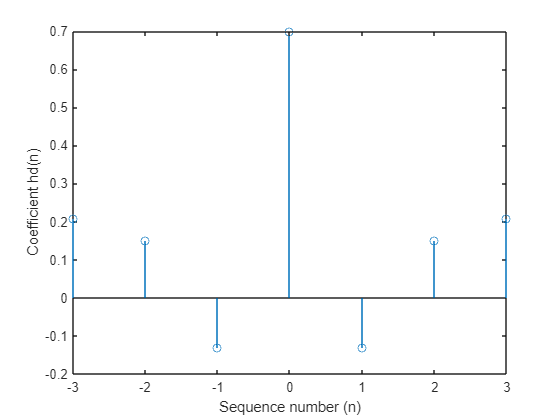

figure
n=-a:a;
stem(n,hd)
xlabel('Sequence number (n)')
ylabel('Coefficient hd(n)')

% Transfer function of IIR filter
numz=hd;
denz=1;
Hz=tf(numz,denz,T)

Hz =
 
  0.207 z^6 + 0.1514 z^5 - 0.1312 z^4 + 0.7 z^3 - 0.1312 z^2 + 0.1514 z + 0.207
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


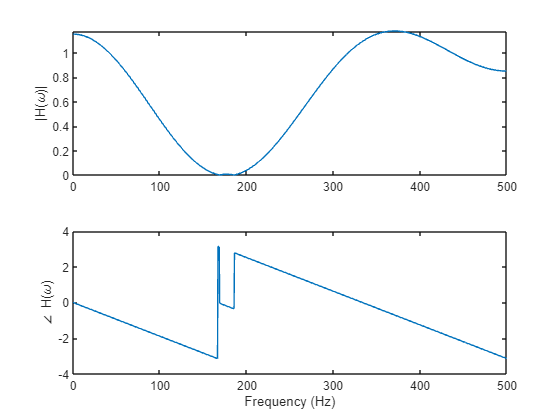

% frequency response of FIR filter
Fs=1000;
[H,f]=freqz(numz,denz,1024,Fs);
H_mag=abs(H);
H_ang=angle(H);
figure
subplot(2,1,1)
plot(f,H_mag)
ylabel('|H(\omega)|')
subplot(2,1,2)
plot(f,H_ang)
ylabel('\angle H(\omega)')
xlabel('Frequency (Hz)')